# Least Squares Regression

Partial differentiation allows us to derive relationships for the slope and intercept of the best-fit straight line $y = a_0 + a_1x$ to data that have uncertainties attached to them. If the uncertainties are only in the dependent variable, then we can easily derive the equations for the unknown parameters 


$$a_0 = \frac{S_yS_{xx} - S_{xy}S_x}{\Delta}, \qquad a_1 =\frac{SS_{xy}-S_xS_y}{\Delta}, \qquad \Delta = SS_{xx} - S_XS_x$$


where


$$S = \sum_{i=1}^{N} \frac{1}{\sigma_i^2},\quad S_x = \sum_{i=1}^{N}\frac{x_i}{\sigma_i^2},\quad S_y = \sum_{i=1}^{N}\frac{y_i}{\sigma_i^2},\quad S_{xx} = \sum_{i=1}^{N}\frac{x_i^2}{\sigma_i^2},\quad S_{xy} = \sum_{i=1}^{N} \frac{x_iy_i}{\sigma_i^2}$$


and where $x_i$ and $y_i$ are the data points. 

To examine how this works in practice, let's use these equations to find the best-fit straight line to some artifical data. 

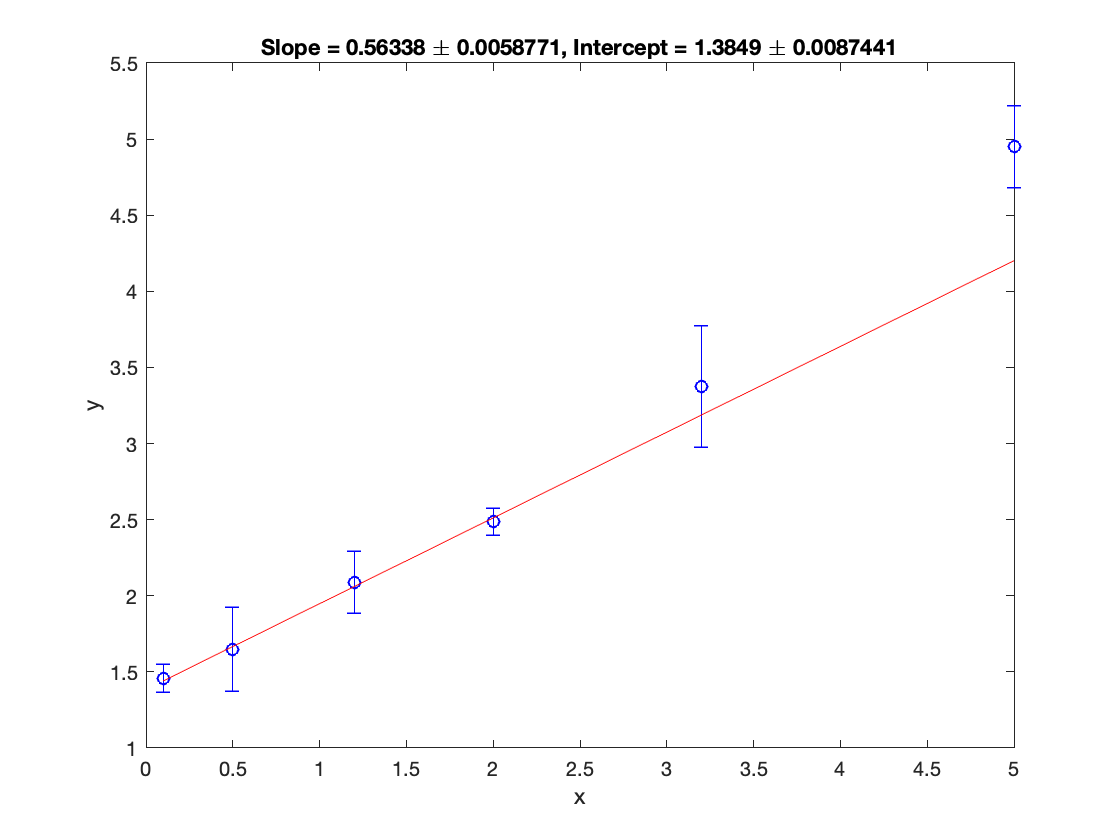

% First set the x-values of the artificial data set.
x      = [0.1, 0.5, 1.2, 2.0, 3.2, 5.0]';
n_data = length(x);

% For each x-value we will create a triplet of y-values calculated 
% using a straight with a given slope and intercept and then adding 
% error terms that are normally distributed with a a zero mean and given
% standard deviation. We also calculate the means of these y-values.
real_slope     = 0.72;
real_intercept = 1.2;
data_std       = 0.2;

y       = real_intercept + real_slope*x + data_std*randn(n_data,3);
y_means = mean(y,2);

% Now we have the data, we calculate the mean and variance of the data
% points, and this becomes our data set of x and y values with associated
% uncertainties. 
var_y = var(y,0,2);
std_y = std(y,0,2);

% Now call the function to calculate the least-squares fitted values of the
% slope and intercept

[fit_slope, del_slope, fit_inter, del_inter] = LeastSquMMEES(x, y_means, var_y);
 
y_fit = fit_inter + fit_slope*x;

figure(1)
errorbar(x,mean(y,2),std_y, 'bo')
title(['Slope = ' num2str(fit_slope) ' \pm ' num2str(sqrt(del_slope)) ', Intercept = ' num2str(fit_inter), ' \pm ' num2str(sqrt(del_inter))])
hold on
xlabel('x')
ylabel('y')
plot(x, y_fit, 'r-')

***Exercise:**** Examine what happens to the uncertainties on the estimates of the slope and intercept as the standard deviation of the triplicate data points *(data_std)* varies. *

The weighted least squares regression finds the equation of the straight line that best fits the data but gives data points with smaller uncertainties more weight than those with larger uncertainties.